# Homework #2

1) A little introductory brain teaser. Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice sum to seven)? What is the ratio of the probabilities?

p_1 = 1/6;
p_1_1 = p_1*p_1

p_1_1 = 0.0278


% 7: 1,6; 2,5; 3,4; 4,3; 5,2; 1,6 (6 ways to roll a 7 with 2 dice); 36
% rolling possibilities total 
p_7 = 6/36

p_7 = 0.1667


ratio_11_7 = p_1_1/p_7

ratio_11_7 = 0.1667

ratio_7_11 = p_7/p_1_1

ratio_7_11 = 6

2) Following what we did in class show how to use the convolution operator to determine the probability of the **sum** of 2 six sided dice. Do both analytically (math & counting) and numerically (computer program). Beware the *implicit* definition of the values (x-axis on histogram).

#### Analytically: 

The probability $\wp_{A+B} \left(x\right)=\int \wp_A \left(z\right)\wp_B \left(x-z\right)\mathrm{dz}=\wp_A \left(x\right)*\wp_B \left(x\right)$ where $*$ denotes "convolution." This equation is useful for calculating the specific probability of rolling some number from a combination of two numbers (x) from dice A and B.

For two six-sided dice, this happens to be discrete, since you can only roll integers 1-6. Therefore, the equation looks more like: $\wp_{A+B} \left(x\right)=\sum_z \wp_A \left(z\right)\wp_B \left(x-z\right)\ldotp$

Here are some examples:

*Rolling a 2 from dice A and B*


$$\wp_{A+B} \left(2\right)=\sum_{z=1}^1 \wp_A \left(z\right)\wp_B \left(x-z\right)=\wp_A \left(1\right)\wp_B \left(1\right)=\frac{1}{6}*\frac{1}{6}=\frac{1}{36}$$


*Rolling an 8 from dice A and B*


$$\wp_{A+B} \left(8\right)=\sum_{z=2}^6 \wp_A \left(z\right)\wp_B \left(x-z\right)=\wp_A \left(2\right)\wp_B \left(6\right)+\wp_A \left(3\right)\wp_B \left(5\right)+\wp_A \left(4\right)\wp_B \left(4\right)+\wp_A \left(5\right)\wp_B \left(3\right)+\wp_A \left(6\right)\wp_B \left(2\right)=5\cdot \frac{1}{36}=\frac{5}{36}$$


Note: The upper and lower bounds are determined by the dice and by the sum. For instance, to roll a 2, each die rolls a minimum of 1, so the only possibility of rolling a 2 is when both dice roll a 1. To roll an 8, you have to consider both bounds of the sum. You have to roll at least a 2 on one of the dice, since 8-1 = 7 and 7 is not a possible roll. Also, due to the nature of the dice, it is impossible to roll a single number greater than 6. 

#### Numerically:

p_n = 1/6;
A = [p_n p_n p_n p_n p_n p_n];
B = A;

prob = conv(A,B)

prob =     0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278


sum(prob)

ans = 1.0000

My variable 'prob' returns a vector of the probability distribution of outcomes for rolling two dice. prob(n) = probability of rolling an outcome of n+1. As you can see, the sum of the elements = 1. 

I'll now graph my distribution, with the outcome on the x-axis and probability on the y. 

xvals = 2:1:12

xvals =      2     3     4     5     6     7     8     9    10    11    12


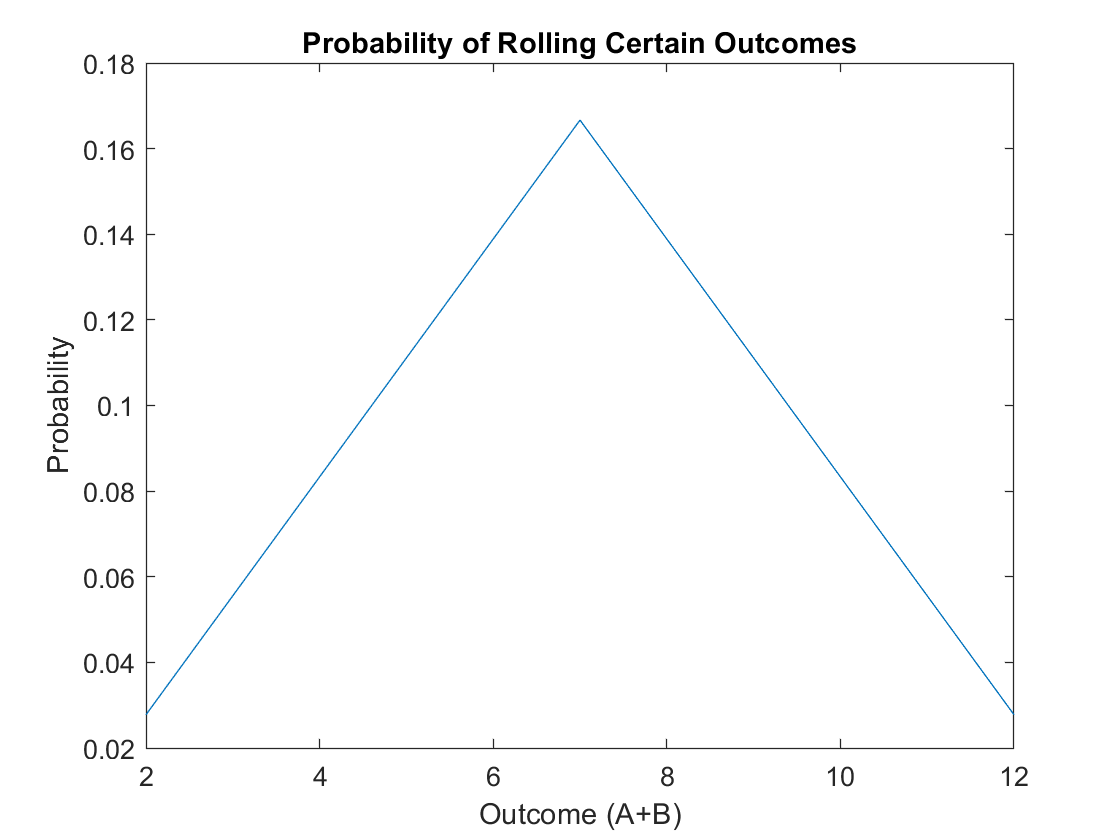

plot(xvals,prob)

title('Probability of Rolling Certain Outcomes')
xlabel('Outcome (A+B)')
ylabel('Probability')

3) Calculate the mean and the variance of the distribution in problem 2. Hint: this is surprisingly tricky, make sure your result makes sense.

weighted = zeros(11,1);

for i = 1:11
    weighted(i) = xvals(i)*prob(i);
end

mu = mean(weighted)

mu = 0.6364


variab = zeros(11,1);

for n = 1:11
    variab(i) = prob(i)*(xvals(i)-mu)^2;
end

variance = sum(variab)

variance = 3.5870

4) Repeat 2, and graph the **average** of 10 dice. Is this is a Gaussian distribution? Explain in depth.

5) Show that the sum and average of an initially Gaussian distribution is also a Guassian (can be analytic or numerical). How does the standard deviation of the resulting sum or average Guassian change? This is a *hugely* important result. Explore what this means for integrating a signal over time.